# Frequency Response 1D mirror

## Preamable

clear all
syms s x
s = tf('s');

opts = bodeoptions("cstprefs");
opts.PhaseWrapping = 'off';
opts.FreqUnits = 'Hz';

## Mass Inertia, and Torsion stiffness

I           = 4.8101e-15;   %kg*m^2
k           = 2.135e-08;    %Nm/rad
f_comsol    = 306;          %Hz

## Eigen Frequentie analesys

f_eig       = sqrt(2*k/I)/2/pi

f_eig = 474.1951

I_comsol    = 2*k/((f_comsol*2*pi)^2)

I_comsol = 1.1551e-14

T           = 1/(I*s^2 + 2*k)

T =
 
             1
  -----------------------
  4.81e-15 s^2 + 4.27e-08
 
Continuous-time transfer function.



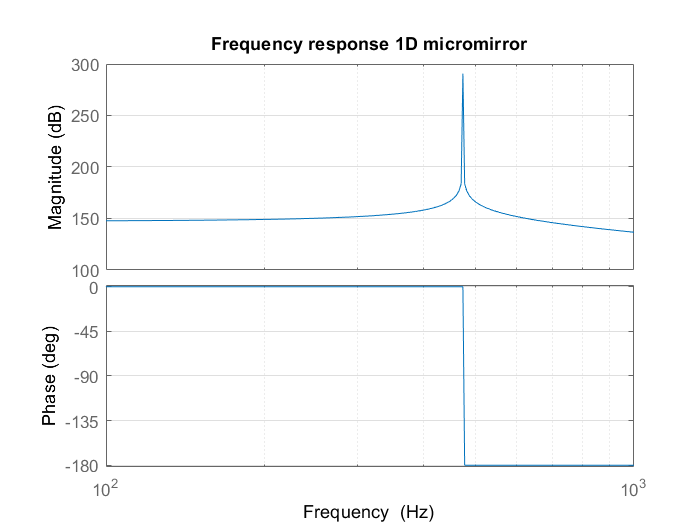

bode(T,opts); title("Frequency response 1D micromirror"); grid on; xlim([1e2 1e3])